Dobbiamo calcolare il temrine gravitazionale e poi utilizzare la seguente formula per il tuning 

del termine proporzionale $K_P $** matrice diagonale e simmetrica:**

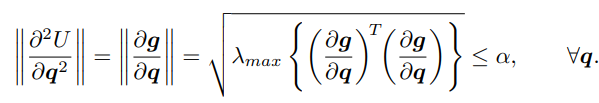     POSSO SEMPRE TROVARE $\alpha
$.

**Una volta trovato **$\alpha
$**  devo scegliere il minimo autovalore della matrice **$K_{P,m}=K_P^T*K_P>\alpha$**.**

**Nota che se **$K_P$** è diagonale allora il più piccolo elemento sulla diagonale deve essere maggiore di **$\alpha$**. Facendo questo vale il seguente teorema**

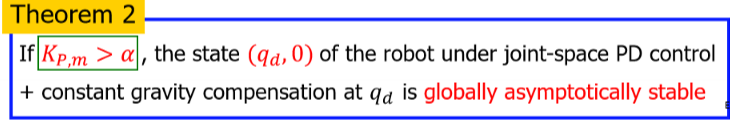

Alla fine capisci anche bene come tunare $K_P
$ . 

**I GRAVITY TERMS E LE VARIABILI DEVONO ESSERE GIA ASSEGNATE**

gravity_terms

$$gravity\_terms = \left(\begin{array}{c} -g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)\\ 0 \end{array}\right)$$

**Calcolo della derivata dei gravity term (Hessiano dell' energia potenziale) e la sua norma**

 

Hessian_U=jacobian(gravity_terms,q)

$$Hessian\_U = \left(\begin{array}{cc} g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right) & 0\\ 0 & 0 \end{array}\right)$$

Calcolo la norma dell' Hessiano

aux=transpose(Hessian_U)*Hessian_U;
[autovettori,autovalori]=eig(aux);
autovalori=simplify(autovalori)

$$autovalori = \left(\begin{array}{cc} 0 & 0\\ 0 & {g_{0}}^{2}\,{\sin\left(q_{1}\right)}^{2}\,{\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)}^{2} \end{array}\right)$$

**CALCOLO Di ALPHA . Questo pezzo deve essere fatto a mano (**troppo tempo per automatizzarlo, infattibile**) **

Adesso devo considerare il massimo degli autovalori per ogni valore di q e farne la radice quadrata.

**Dopo di che alpha deve essere minore o uguale al valore che otteniamo.**

Qui sostituisci il seni e coseni con 1 e vedi quale valore è piu grande.

**Nota** che in base alle dipendenze che ci sono all' interno dei gravity terms potremmo avere questo vincolo $K_{P,m}=K_P^T*K_P>\alpha$ solo su una o alcune componenti di $K_P$ mentre le altre sono libere basta che siano positive.

Tipo se ho questa situazione 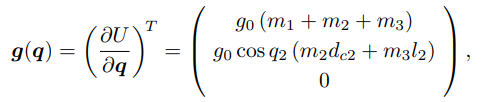 si vede come g dipende solo da q2 e questo significa che devo avere $K_{P,2}>\alpha$ mentre le altre due componenti della diagonale di $K_P$ sono liberi basta che siano positivi

**Nota:**

Se ti chiede di fare il tuning anche di $K_D$ :

       - **Se ****non**** hai attrito, allora necessariamente **$K_D>0$

       - **Se ****hai**** attrito , allora puoi settare **$K_D=0$** ma puoi anche mettere **$K_D>0$